# **Escuela CNS: Analisis de series de tiempo - Día 2**

## Obtencion de parametros

A lo largo de las siguientes secciones, se obtendrán, a partir de la señal previamente procesada, una serie de parámetros que nos ayudarán a entender qué ocurre durante los episodios. Estos parámetros son los siguientes:

- Factor de cresta

- Variabilidad de la frecuencia cardíaca (HRV)

- Amplitud de las espigas R

A cada uno de los parámetros mencionados se le calculará su tasa de cambio. Esto es relevante porque la variabilidad biológica es un fenómeno natural presente en estos parámetros, pero durante los episodios dicha variabilidad tiende a aumentar. Por ello, resulta de especial interés identificar los puntos donde esta variabilidad se acentúa.

Vamos a empezar corriendo la sección del día anterior, que contiene la señal ya obtenida y procesada.

% Leer datos desde archivo MAT
load("px_actividad.mat");

% Separar columnas de tiempo y valor de la señal
% tiempo = data(:, 1);
% valor = data(:, 2);

% tiempo = tiempo(1:8500000);
% valor = valor(1:8500000);

fs=250;

tiempo = seconds(tiempo); 
tiempo.Format = 'hh:mm:ss.SSS';

inicio_episodios = [
    duration("00:37:06.711"), 
    duration("00:47:44.443"), 
    duration("02:23:13.895"), 
    duration("03:19:55.153"), 
    duration("04:02:35.684"), 
    duration("04:37:11.904"), 
    duration("08:32:06.960")
];

fin_episodios = [
    duration("00:38:43.887"), 
    duration("00:48:16.300"), 
    duration("02:23:35.885"), 
    duration("03:20:12.715"), 
    duration("04:05:09.748"), 
    duration("04:37:31.979"), 
    duration("08:32:24.941")
];

periodo_sano = [duration("00:21:44.711"), duration("00:23:44.443")];

inicio_episodios_sec = seconds(inicio_episodios);
fin_episodios_sec = seconds(fin_episodios);

% === Filtro de media móvil + paso alto ===
window_size = 150;
valor_filtrado_ma = movmean(valor, window_size);
paso_altas_ma = valor - valor_filtrado_ma;

% === Filtro Butterworth de orden 5 ===
order = 5;
[b5, a5] = butter(order, 20 / (fs / 2), 'low');
valor_filtrado = filtfilt(b5, a5, paso_altas_ma);

# Sección #2

Para empezar con el proceso de analisis, se ubicaran las espigas R y se guardara su pocicison usando la funcion FindPeaks

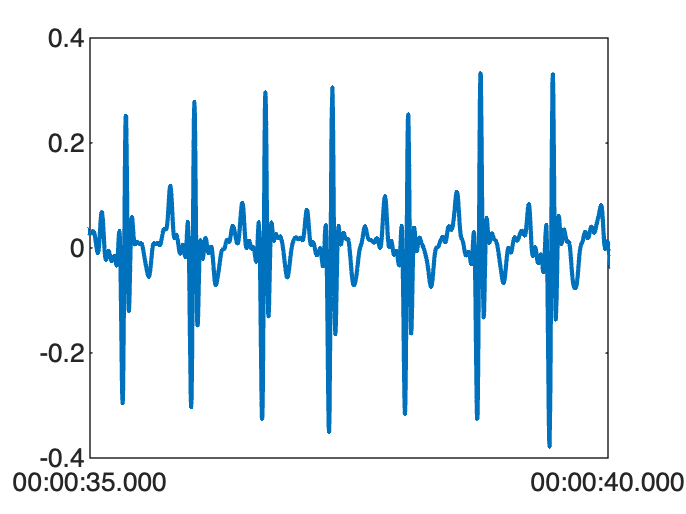

%hacer un primer plot para ver la amplitud
figure;
plot(tiempo,valor_filtrado, 'LineWidth', 1.5);
xlim([seconds(35) seconds(40)])


% Detectar espigas R en TODA la señal ~ ~

[~, locs] = findpeaks(valor_filtrado, "MinPeakHeight", 0.5, "MinPeakDistance", 0.20*fs);

length(locs)

ans = 902

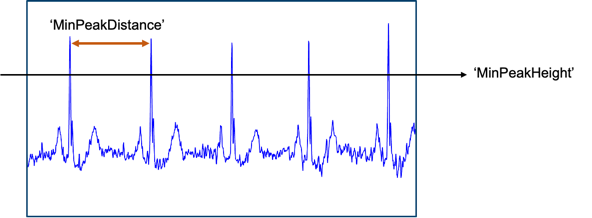

Otra parte importante del proceso, es poder identificar la tasa de cambio de cada uno de uno de estos parámetros hechos como serie temporal. Esto nos ayudará a identificar tendencias importantes que auxilares en la identificación de episodios anómalos

# Sección #3

### Visualización de las espigas R detectadas en los episodios de fibrilación auricular

Recordemos que hay un total de 7 episodios de fibirlación en toda la serie temporal, en esta sección ustedes podrán observar y verificar que todas la espigas R son detectadas propiamente sobretodo, en los episodios de PAF.

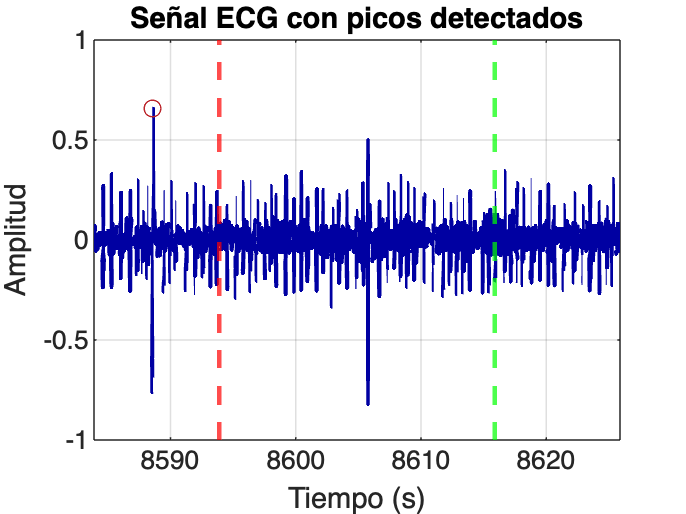

% Por favor, elige el episodio que quieras visualizar
%============================================
episodio = 3;
%============================================

extra = 10;
distancias_muestras = diff(locs);
distancias_tiempo = distancias_muestras / fs;
figure;

ax1 = subplot(1,1,1);
plot((0:length(valor_filtrado)-1)/fs, valor_filtrado, 'Color', '#0000A2', 'LineWidth', 1.5);
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

plot(locs/fs, valor_filtrado(locs), 'o', 'Color', '#BC272D');
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal ECG con picos detectados');

if episodio >= 1 && episodio <= length(inicio_episodios_sec)
    xlim([inicio_episodios_sec(episodio) - extra, fin_episodios_sec(episodio)+extra]);
else
    warning('Número de episodio invalido');
end

grid on;

# Sección #4

## **Variabilidad de ritmo cardiaco - HRV **

**El HRV es una medida de las fluctuaciones en los intervalos de tiempo entre latidos cardíacos consecutivos, conocidos como intervalos R-R en un electrocardiograma.**

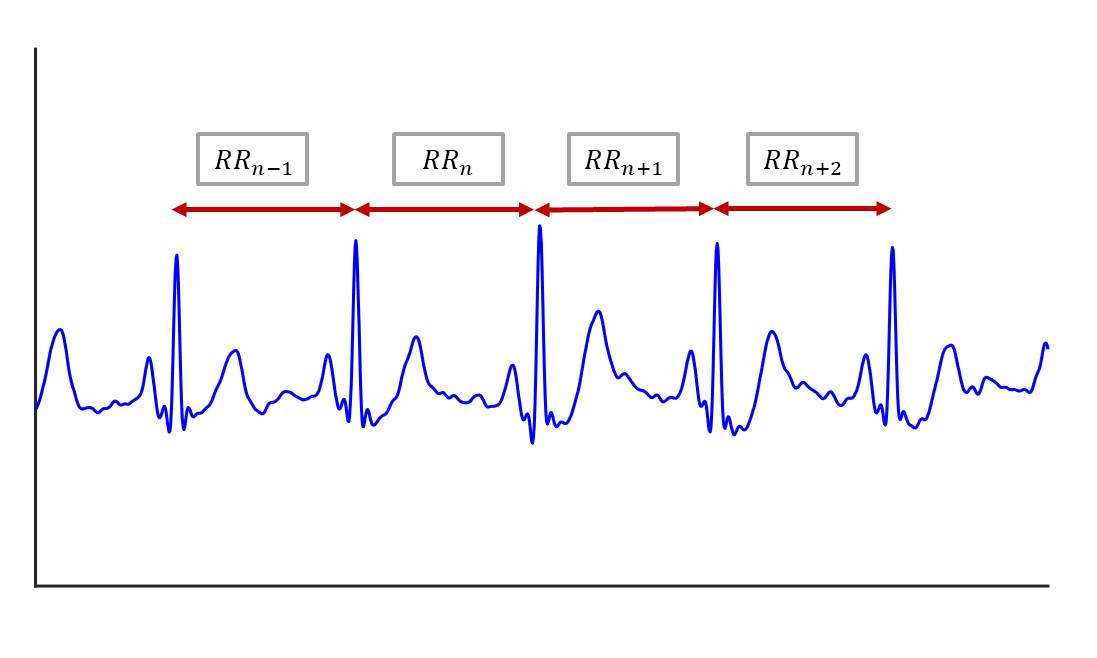


%Asignar los tiempos de las ondasR y de los intervalos R-R
tiempo_sec = seconds(tiempo);

R_times = tiempo_sec(locs);

RR_intervals_sec = diff(R_times);


%suavizar la serie de tiempo de los intervalos R-R
RR_intervals_filtered = movmean(RR_intervals_sec,20)

RR_intervals_filtered =   140.3688
  127.9971
  118.1260
  119.9505
  114.2897
  107.6744
  101.3890
   96.8619
   91.5236
   88.2611


## Sección 4.1

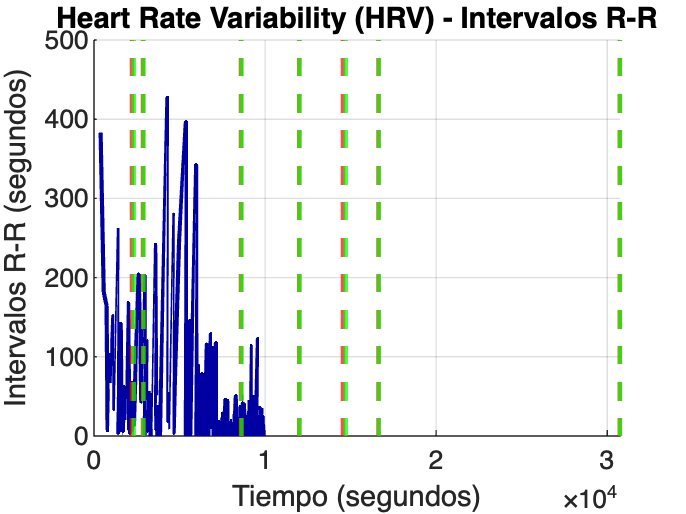

% Gráfica de la serie de tiempo
figure;
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

plot(R_times(2:end), RR_intervals_sec, 'b-', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', '#0000A2');
xlabel('Tiempo (segundos)');
ylabel('Intervalos R-R (segundos)');
title('Heart Rate Variability (HRV) - Intervalos R-R');
grid on;

## Sección 4.2

% Calcular tasa de cambio (dHRV/dt)
dHRV_dt = abs(diff(RR_intervals_sec) ./ diff(R_times(2:end)))

dHRV_dt =     1.1085
    0.1048
    2.4036
    5.3031
    0.9253
    0.4789
    0.5403
    3.3918
    0.8680
   59.9000


% vector de tiempo para la derivada 
time_derivative = R_times(3:end);

dHRV_dt = movmean(dHRV_dt, 20);
%suavizar la serie de tiempo de los intervalos R-R

## Sección 4.3

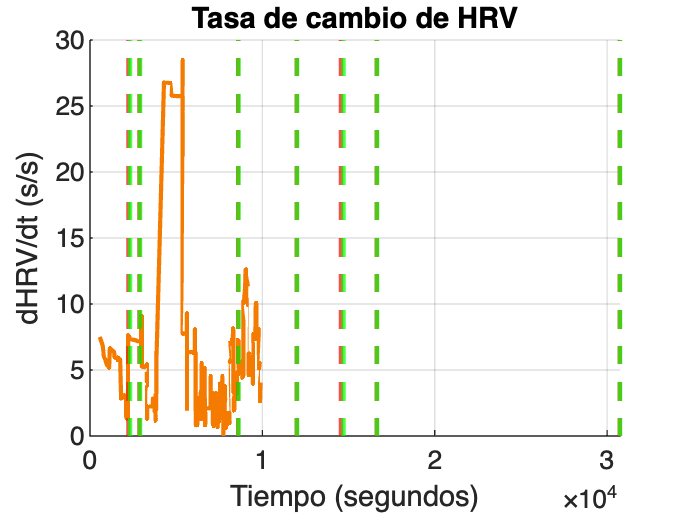

% Gráfica de la tasa de cambio 
figure;
hold on;
plot(time_derivative, dHRV_dt, 'r-', 'LineWidth', 1.5, 'Color', '#F47A00');

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

xlabel('Tiempo (segundos)');
ylabel('dHRV/dt (s/s)');
title('Tasa de cambio de HRV');
grid on;

## Sección 4.4

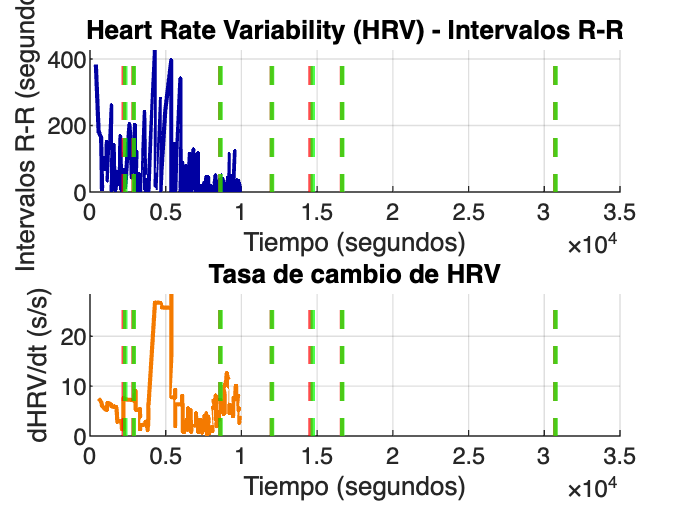

% Graficos
figure;
subplot(2, 1, 1);
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
end
for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

plot(R_times(2:end), RR_intervals_sec, 'b-', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', '#0000A2');
xlabel('Tiempo (segundos)');
ylabel('Intervalos R-R (segundos)');
title('Heart Rate Variability (HRV) - Intervalos R-R');
grid on;

subplot(2,1,2);
hold on;
plot(time_derivative, dHRV_dt, 'r-', 'LineWidth', 1.5, 'Color', '#F47A00');

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.6);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.6);
end

xlabel('Tiempo (segundos)');
ylabel('dHRV/dt (s/s)');
title('Tasa de cambio de HRV');
grid on;


ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

% Enlazar los ejes X (tiempo) de ambos subplots
linkaxes([ax1, ax2], 'x');

# Sección #5

## Factor de cresta

El factor de cresta se define como el cociente entre el valor pico o valor máximo de una señal, y su valor eficaz también conocido como RMS o RootMean Square.  Esta medida es adimensional y entre sus principales aplicaciones podemos encontrar la evaluación de distorsiones en señales eléctricas y calidad de audio o la identificación de eventos nacientes que puedan llevar a una falla en sistemas mecánicos.

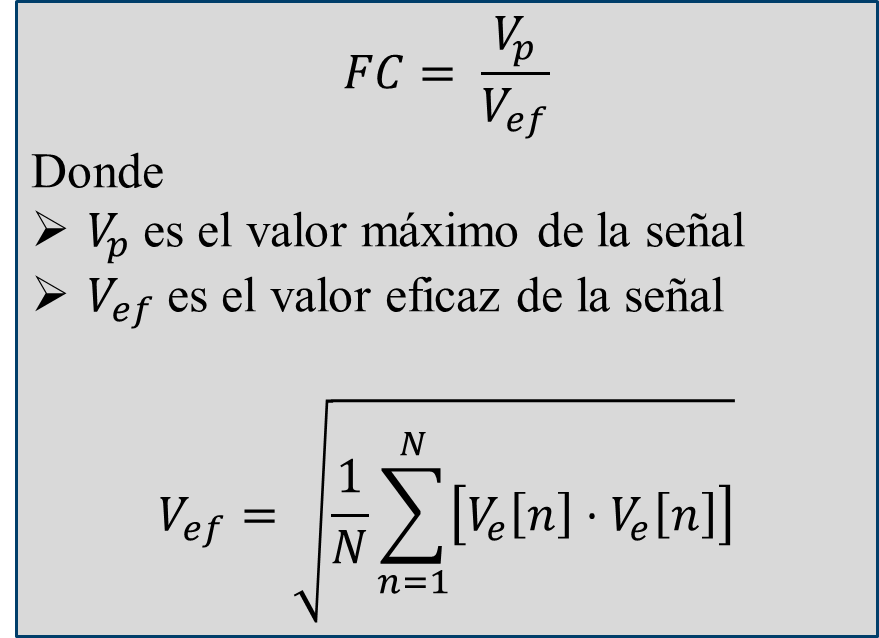


ventana_seg = 6;
ventana_muestras = round(ventana_seg * fs);

% Inicialización
n_muestras = length(valor_filtrado);
num_ventanas = floor(n_muestras / ventana_muestras);

cresta = zeros(1, num_ventanas);
tiempo_fc = zeros(1, num_ventanas);


for k = 1:num_ventanas
    % Índices de la ventana actual
    idx_inicio = (k - 1) * ventana_muestras + 1;
    idx_fin = k * ventana_muestras;
   
    segmento = valor_filtrado(idx_inicio : idx_fin);
    
    % Cálculo del factor de cresta
    rms_val = rms(segmento);
    pico_val = max(abs(segmento));
    factor_cresta = pico_val / rms_val;
    
    % Guardar resultados
    cresta(k) = factor_cresta;
    tiempo_fc(k) = (idx_inicio + idx_fin)/ 2 / fs;
end

%suavizado de la serie de tiempo

cresta = movmean(cresta, 20);

## Sección 5.1

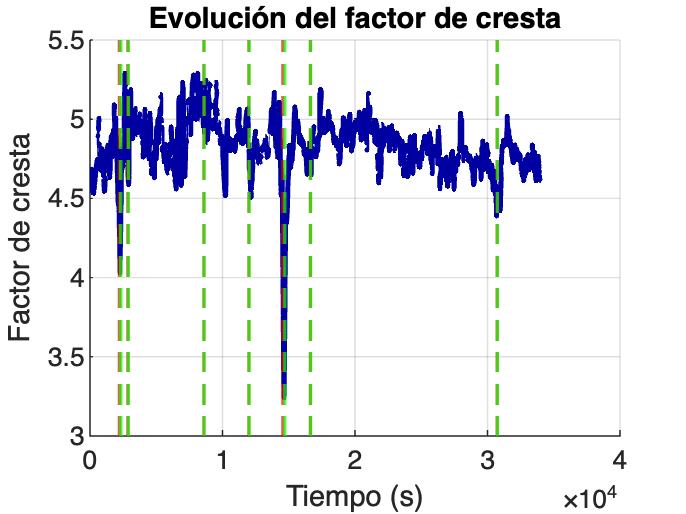

% Gráfica de la serie de tiempo

figure;
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

plot(tiempo_fc, cresta, '-', 'LineWidth', 1.8, 'Color', '#0000A2');
xlabel('Tiempo (s)');
ylabel('Factor de cresta');
title('Evolución del factor de cresta');
grid on;

## Sección 5.2

% Tasa de cambio (derivada temporal del factor de cresta)
tasa_cambio = abs(diff(cresta) ./ diff(tiempo_fc));

tiempo_fc_derivada = tiempo_fc(2:end) + diff(tiempo_fc);


%suavizado de la serie de tiempo

tasa_cambio = movmean(tasa_cambio,20);

## Sección 5.3

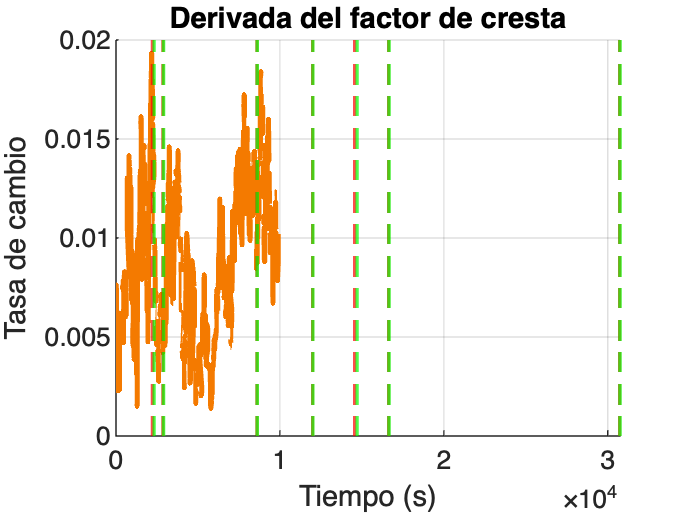

%Gráfica de tasa de cambio

figure;
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

plot(tiempo_fc_derivada, tasa_cambio, '-', 'LineWidth', 1.8, 'Color', '#F47A00');
xlabel('Tiempo (s)');
ylabel('Tasa de cambio');
title('Derivada del factor de cresta');
grid on;

## Sección 5.4

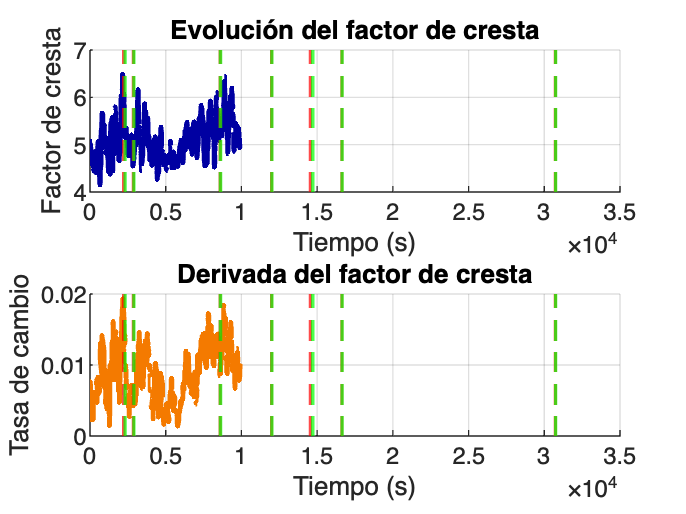

% === Gráficas ===
figure;

% 1. Factor de cresta
subplot(2,1,1);
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

plot(tiempo_fc, cresta, '-', 'LineWidth', 1.8, 'Color', '#0000A2');
xlabel('Tiempo (s)');
ylabel('Factor de cresta');
title('Evolución del factor de cresta');
grid on;

% 2. Tasa de cambio
subplot(2,1,2);
hold on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

plot(tiempo_fc_derivada, tasa_cambio, '-', 'LineWidth', 1.8, 'Color', '#F47A00');
xlabel('Tiempo (s)');
ylabel('Tasa de cambio');
title('Derivada del factor de cresta');
grid on;

% Sincronizar eje x
linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');

# Sección #6

## Amplitud de espigas R

En esta seccion se calculara el promedio de la amplitud de las espigas R por intervalos de seis segundos.

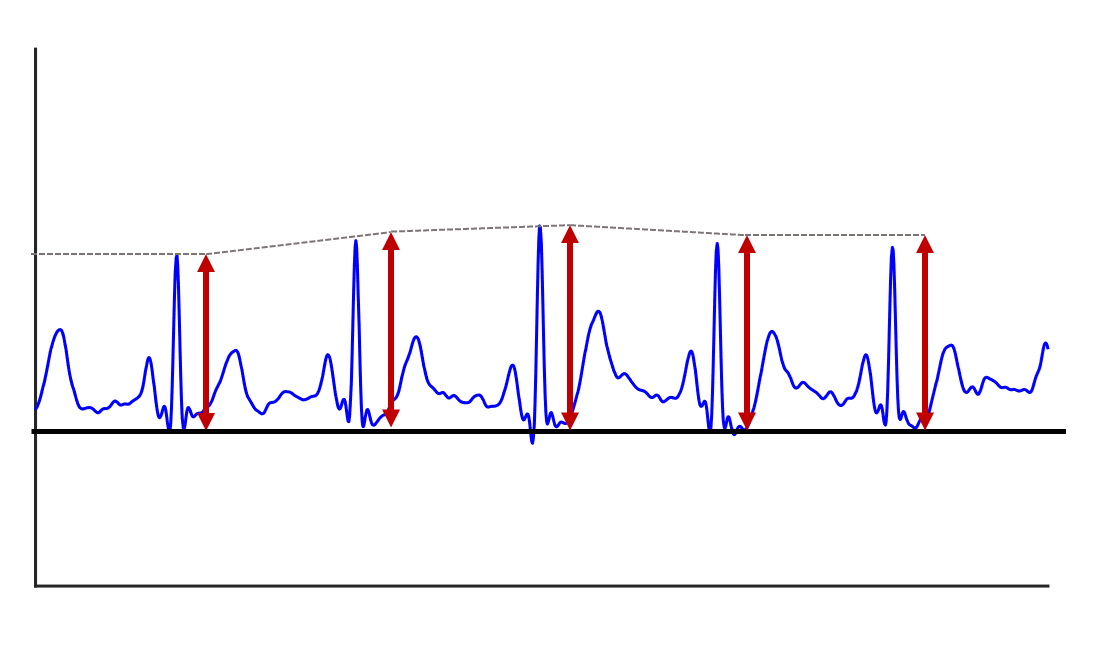

% --- Parámetros ---
ventana_seg = 6;                      % Duración de cada ventana en segundos
ventana_muestras = round(ventana_seg * fs);  % Duración en muestras

% --- Inicialización ---
n_muestras = length(valor_filtrado);
num_ventanas = floor(n_muestras / ventana_muestras);

amplitud_R = zeros(1, num_ventanas);      % amplitudes promedio por ventana
tiempo_R = zeros(1, num_ventanas);        % tiempos centrales de cada ventana

% --- Calcular amplitud promedio de espigas R por ventana ---
for k = 1:num_ventanas
    % Índices de la ventana actual
    idx_inicio = (k - 1) * ventana_muestras + 1;
    idx_fin = k * ventana_muestras;
    
    % Tiempo central de la ventana en segundos
    tiempo_R(k) = (idx_inicio + idx_fin) / 2 / fs;
    
    % Picos R dentro de esta ventana (usando posiciones 'locs')
    locs_en_ventana = locs(locs >= idx_inicio & locs <= idx_fin);
    
    if ~isempty(locs_en_ventana)
        % evaluar amplitudes de las espigas R 
        amplitudes = valor_filtrado(locs_en_ventana);
        amplitud_R(k) = mean(amplitudes);  % promedio de amplitudes en la ventana
    else
        amplitud_R(k) = NaN;  % si no hay picos R en esa ventana
    end
end


% --- Suavizado de la serie de tiempo ---




## Sección 6.1

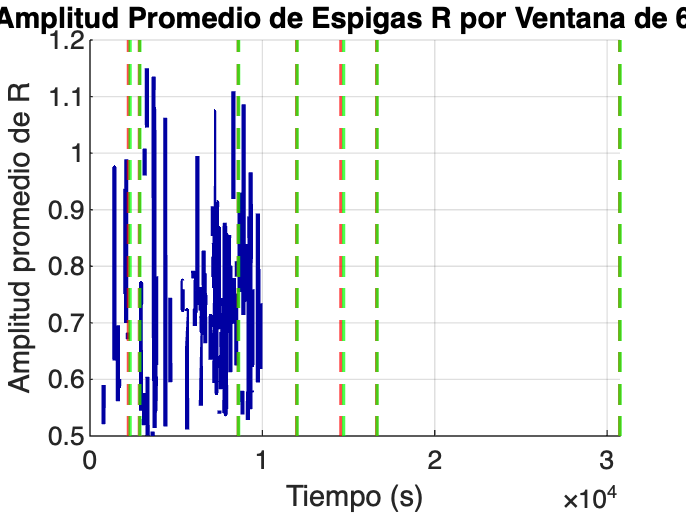

% --- Gráfica de la serie de tiempo ---

figure;
hold on;
plot(tiempo_R, amplitud_R, '-', 'LineWidth', 1.5, 'Color', '#0000A2');
xlabel('Tiempo (s)');
ylabel('Amplitud promedio de R');
title('Amplitud Promedio de Espigas R por Ventana de 6 s');
grid on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

## Sección 6.2

% --- Tasa de cambio de la amplitud de espigas R ---

tasa_cambio_amp = abs(diff(amplitud_R) ./ diff(tiempo_R));

tiempo_cambio_amp = tiempo_R(2:end) + diff(tiempo_R);

tasa_cambio_amp = movmean (tasa_cambio_amp, 20);

% --- Suavizado ---

## Sección 6.3

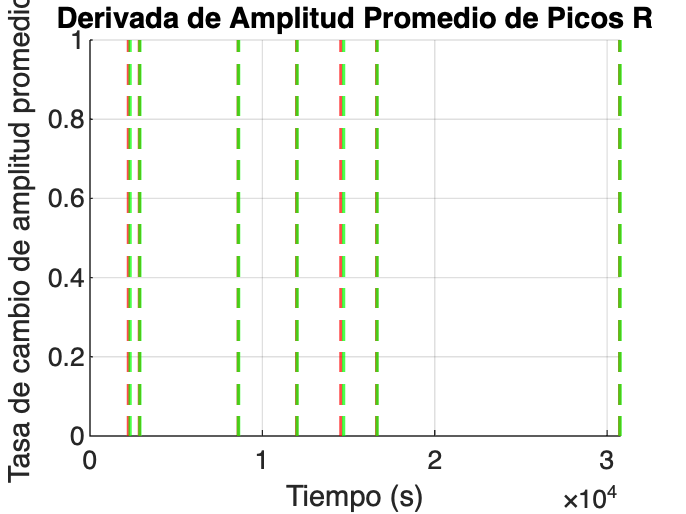

% --- Gráfica de la tasa de cambio ---

figure;
hold on;
plot(tiempo_cambio_amp, tasa_cambio_amp, '-', 'LineWidth', 1.5, 'Color', '#F47A00');
xlabel('Tiempo (s)');
ylabel('Tasa de cambio de amplitud promedio');
title('Derivada de Amplitud Promedio de Picos R');
grid on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

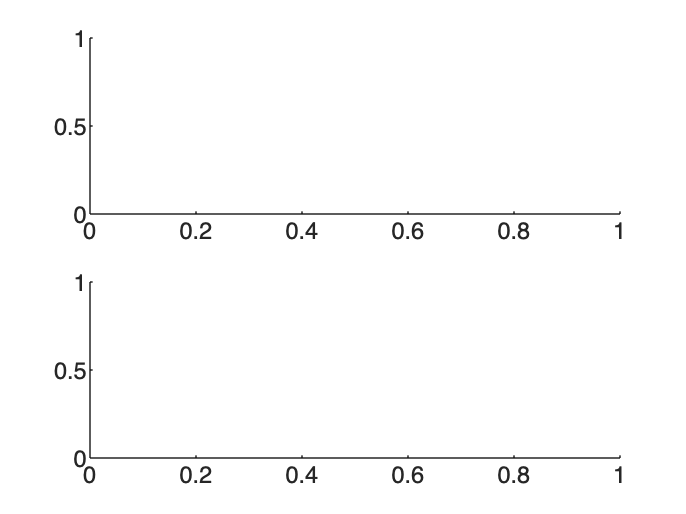


linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');

## Sección 6.4

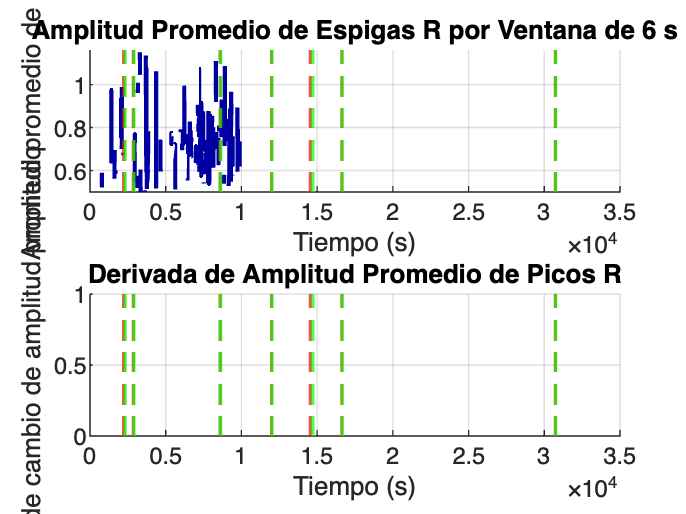

% --- Gráficas ---
figure;

% Subplot 1: Amplitud promedio
subplot(2,1,1);
hold on;
plot(tiempo_R, amplitud_R, '-', 'LineWidth', 1.5, 'Color', '#0000A2');
xlabel('Tiempo (s)');
ylabel('Amplitud promedio de R');
title('Amplitud Promedio de Espigas R por Ventana de 6 s');
grid on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

% Subplot 2: Tasa de cambio
subplot(2,1,2);
hold on;
plot(tiempo_cambio_amp, tasa_cambio_amp, '-', 'LineWidth', 1.5, 'Color', '#F47A00');
xlabel('Tiempo (s)');
ylabel('Tasa de cambio de amplitud promedio');
title('Derivada de Amplitud Promedio de Picos R');
grid on;

for i = 1:length(inicio_episodios_sec)
    xline(inicio_episodios_sec(i), '--r', 'LineWidth', 1.2);
end

for i = 1:length(fin_episodios_sec)
    xline(fin_episodios_sec(i), '--g', 'LineWidth', 1.2);
end

linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');

## **Ahora, por favor, tomen la serie de tiempo px_actividad y calculen los parámetros.**